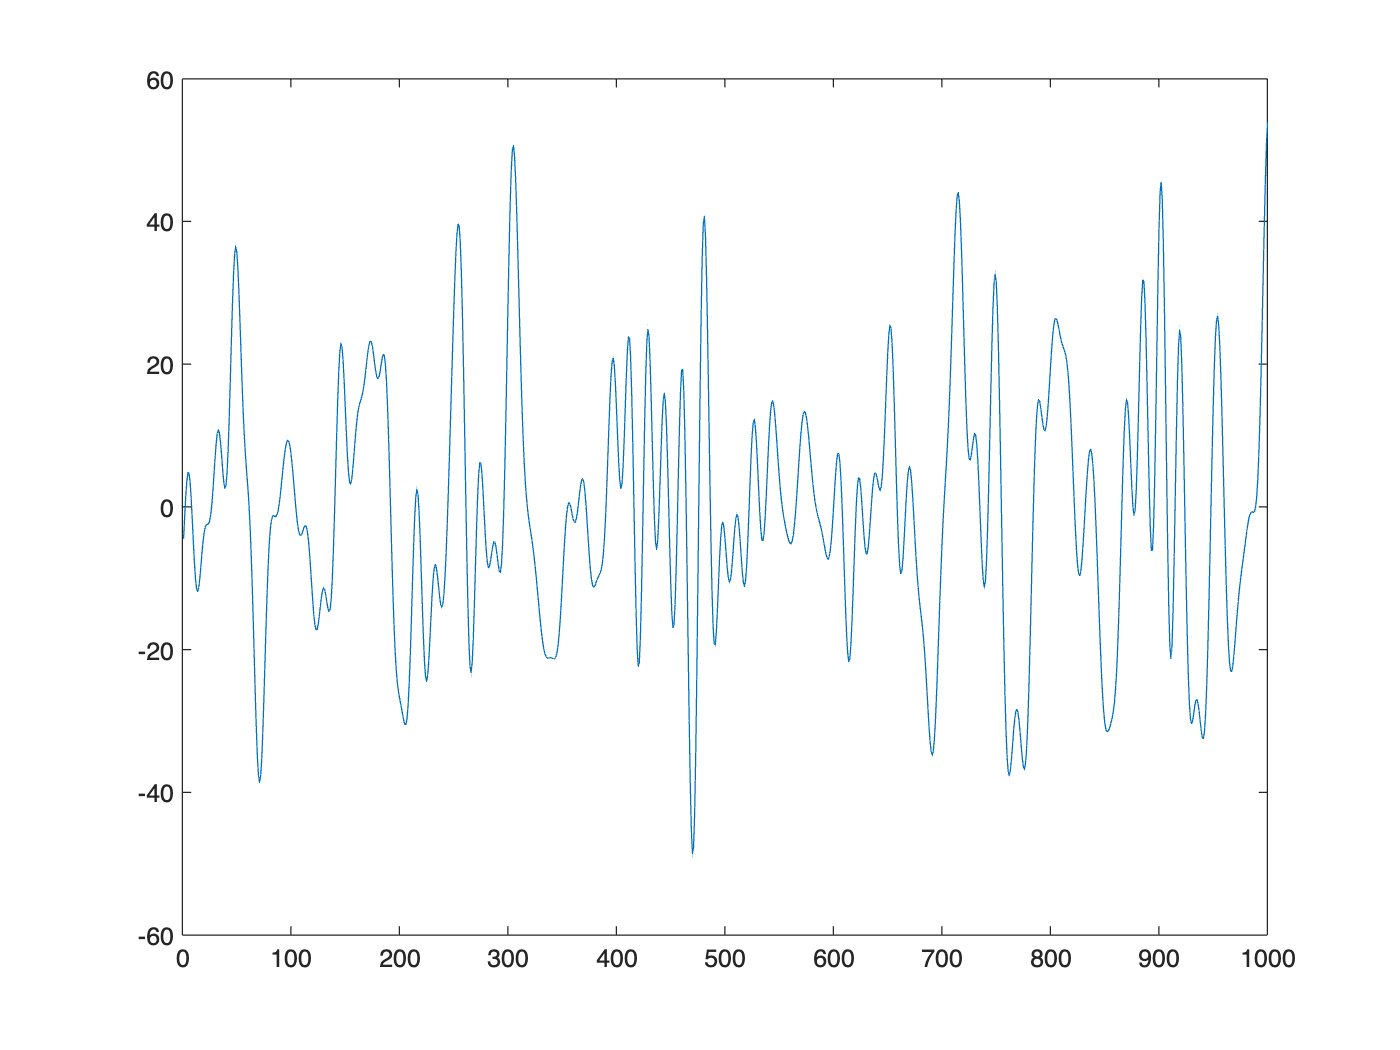

%% Higher Order Connectivivty beyond Pairwise Interaction
% (C) 2025 Moo K. Chung
% University of Wisconsin-Madison
% mkchung@wisc.edu

load rsfMRI4subjects.mat
% variable rsfMRI contains
% 1000 time points x 116 regions x 4 subjeccts
% Display simulted time series

figure; plot(rsfMRI(:,1,1))

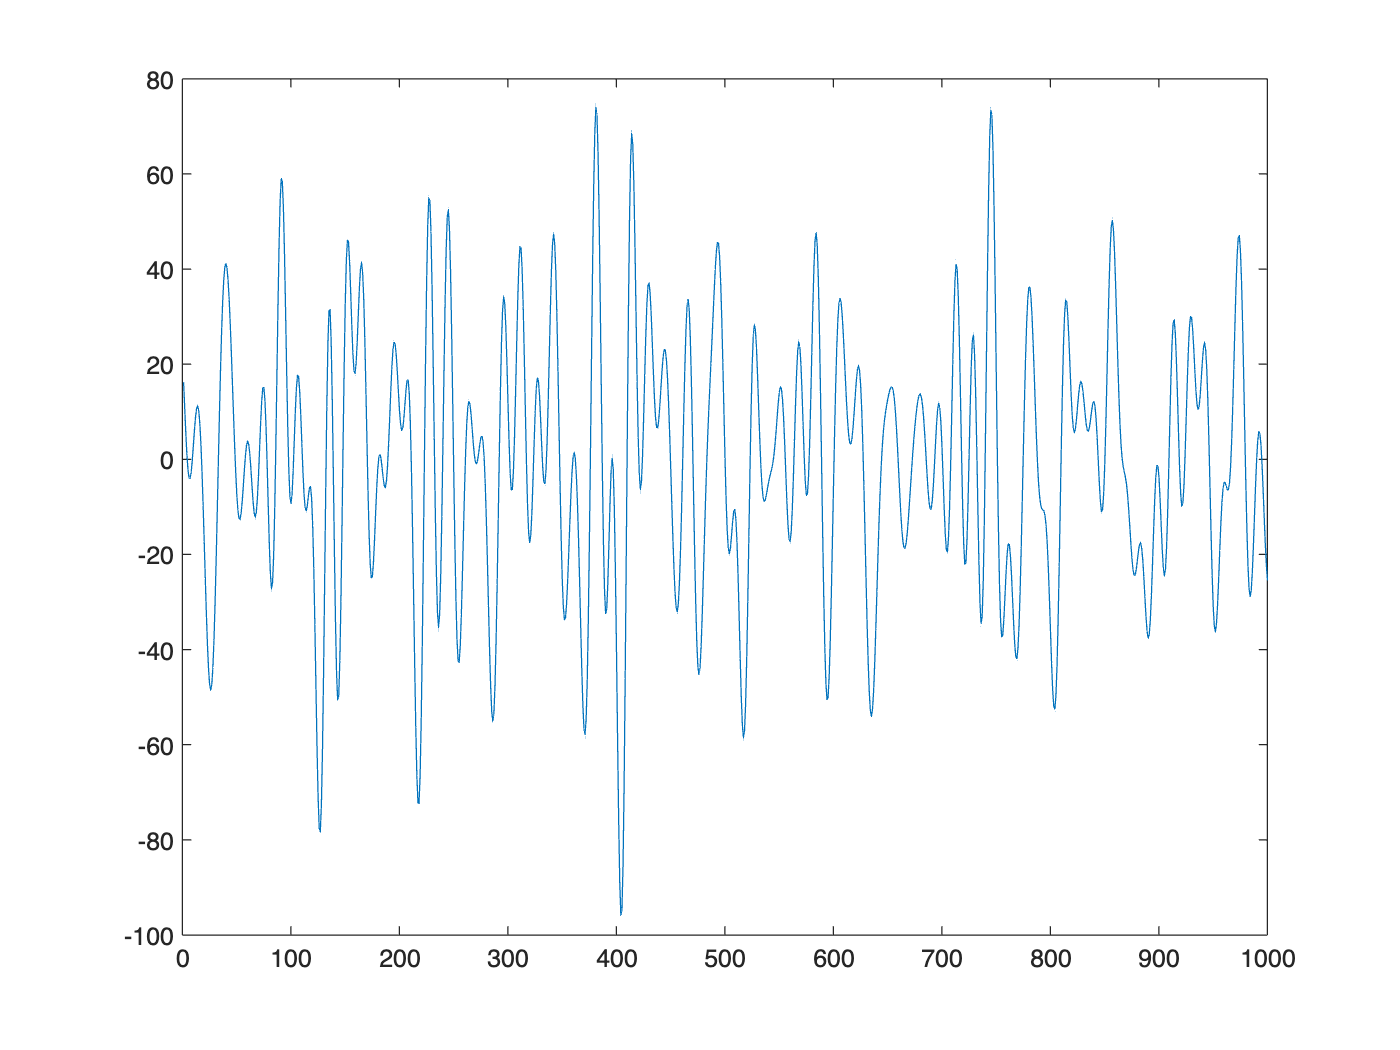

%....
figure; plot(rsfMRI(:,116,1))

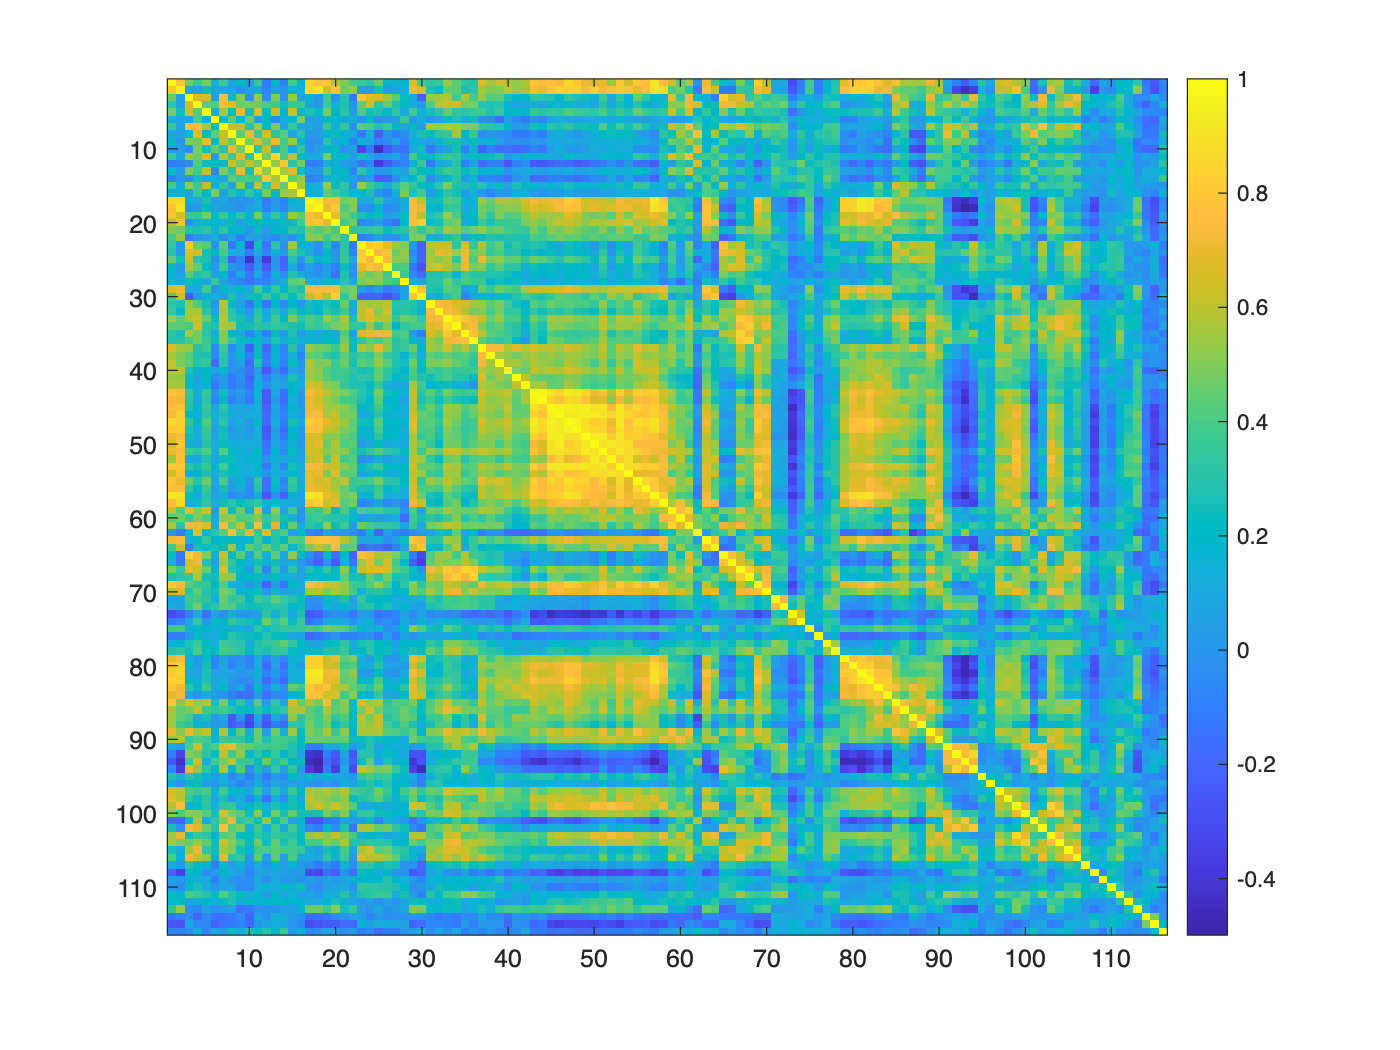

%Correlation over whole time points
windowSize=1000;
X=rsfMRI(:,:,1);
connectivity = sliding_window(X, windowSize);
figure; imagesc(connectivity); colorbar

tau=0.7;
maxDim=3;

%brute-force apporach
tic
S = PH_connectivity2simplex(connectivity, tau, maxDim)

S = 1×4 cell array
    {116×1 double}    {396×2 double}    {1318×3 double}    {3506×4 double}


toc

Elapsed time is 31.178450 seconds.


%464 times faster iterative algorithm that build higher-dimensional
%simplical complex from lower dimensional simplical complex

tic
S = PH_connectivity2simplex_iterative(connectivity, tau, maxDim)

S = 1×4 cell array
    {116×1 double}    {396×2 double}    {1318×3 double}    {3506×4 double}


toc

Elapsed time is 0.056309 seconds.


B = PH_boundary(S)

B = 3×1 cell array
    { 116×396  double}
    { 396×1318 double}
    {1318×3506 double}



% β₀ counts connected components.
% β₁ counts independent cycles (loops) that are not the boundary of any 2-simplex.
% β₂ counts 2-dimensional voids (or cavities).
betti = PH_boundary_betti(B)

betti =     33     9     0
